% Set time units for the year 2024 (a leap year)
setTimeUnitsInWorkspace(2024);

% Create a grid 
Grid = cartGrid(0:20:10000, 0:20:11000, [0 20]);


% Assign a constant hydraulic conductivity (assume sandy material) 
Grid.properties.hydraulic_conductivity = 1.0e-03 * ones(3, Grid.Nx, Grid.Ny, Grid.Nz);

% Define grid porosity
Grid.properties.porosity = 0.2*ones(Grid.Nx,Grid.Ny,Grid.Nz);

% 2D Grid (one model slice) for 2D plotting purposes
G2D = cartGrid(0:20:10000, 0:20:11000);

% Define well coordinates in terms of grid indices (same as before)
well_coords.xinj = [160, 202, 240, 346];
well_coords.yinj = [364, 162, 249, 259];
well_coords.xpmp = [208, 216, 295, 287];
well_coords.ypmp = [342, 206, 229, 289];

% ...
coord_wx = @(i) (i-1)*Grid.hx + Grid.hx/2;
coord_wy = @(j) (j-1)*Grid.hy + Grid.hy/2;

xinj = coord_wx(well_coords.xinj); 
yinj = coord_wy(well_coords.yinj);
xpmp = coord_wx(well_coords.xpmp);
ypmp = coord_wy(well_coords.ypmp);

Q2 = 70/hour;                          % flow rate in I2/P2 doublet
Q1 = 85/hour;                          % flow rate in all other doublets

% Add injection wells
W = verticalWell([], Grid, 160, 364, 1, Q1, 'type', 'injection', 'name', 'I1', 'radius', 0.15);
W = verticalWell(W, Grid, 202, 162, 1, Q2, 'type', 'injection', 'name', 'I2', 'radius', 0.15);
W = verticalWell(W, Grid, 240, 249, 1, Q1, 'type', 'injection', 'name', 'I3', 'radius', 0.15);
W = verticalWell(W, Grid, 346, 259, 1, Q1, 'type', 'injection', 'name', 'I4', 'radius', 0.15);

% Add production wells
W = verticalWell(W, Grid, 208, 342, 1, Q1, 'type', 'pumping', 'name', 'P1', 'radius', 0.15);
W = verticalWell(W, Grid, 216, 206, 1, Q2, 'type', 'pumping', 'name', 'P2', 'radius', 0.15);
W = verticalWell(W, Grid, 295, 229, 1, Q1, 'type', 'pumping', 'name', 'P3', 'radius', 0.15);
W = verticalWell(W, Grid, 287, 289, 1, Q1, 'type', 'pumping', 'name', 'P4', 'radius', 0.15);

Let's plot the locations of injection and pumping wells. 

% Plot the wells using the plotWells function
%plotWells(Grid, well_coords);

% Simulate hydraulic heads in the aquifer subject to bc's
tic; [H,V] = head(Grid, W); toc;

Number of PCG iterations = 51
Residual norm error      = 7.78412E-07
Elapsed time is 0.752290 seconds.


Plot hydraulic heads 

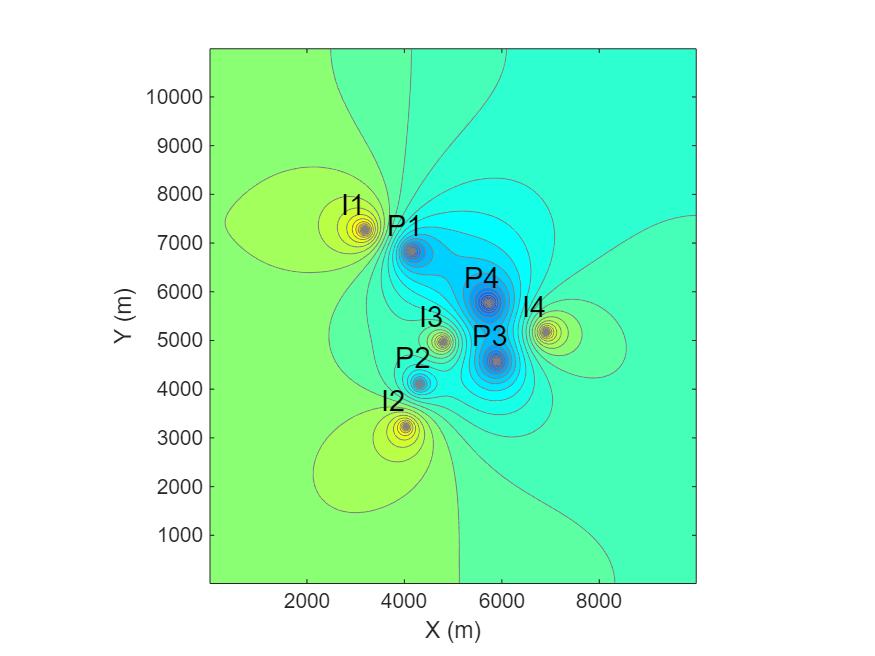

figure; 
opts.fill = 'on';

% plot layer 1 (the only one)
plotContourData(G2D, H(:), opts, ... 
    'LevelList',round(min(H(:))):0.05:round(max(H(:))), ...
    'Color',rgb(Color,'gray'), 'LineWidth', 0.5);
colormap(jet(41));
text([xinj,xpmp]-500, [yinj,ypmp]+500, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
axis tight equal; 
xlabel('X (m)'); ylabel('Y (m)');

%TODO

% 1) Add a way to specify fixed pressure/head BC's in the single phase solver.
%    We start with Dirichlet BC's

% 2) Options for hydraulic conductivity tensor: constant, diagonal, symmetric, full. 

% 3) Integrate the Pollock.m script from MRST for particle tracking

% 4) Add a function to track particles numerically using MATLAB built-in functions.

% 5) Visualize simulated streamlines or pathlines by superimpossing them on
% the top of the hydraulic head plot. 

### Calculate pumping wells catchments

% 
tic;
[pump_well_index,pump_well_volume,~] = pumpingCatchments(Grid, V, W);

iterative solution by bicgstab and incomplete factorization preconditioning methods converged in 1 iterations
iterative solution by bicgstab and incomplete factorization preconditioning methods converged in 0.5 iterations
iterative solution by bicgstab and incomplete factorization preconditioning methods converged in 1 iterations
iterative solution by bicgstab and incomplete factorization preconditioning methods converged in 1 iterations


toc;

Elapsed time is 3.196720 seconds.


### Plot pumping wells catchments

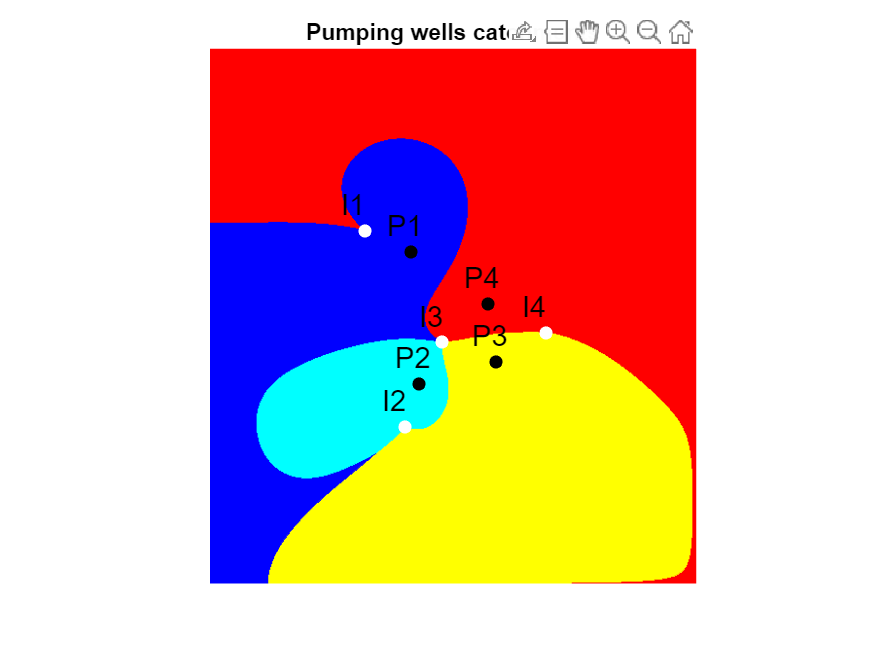

figure;
colormap(jet(4));
plotCellData(G2D,pump_well_index,'EdgeColor','none');
axis tight equal off; colorbar off;
title('Pumping wells catchments'); 
xlabel('X (m)'); ylabel('Y (m)');
hold on; 
scatter(xinj,yinj,40,'w','filled');
scatter(xpmp,ypmp,40,'k','filled');
text([xinj,xpmp]-500, [yinj,ypmp]+500, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
hold off;

tic;
[inj_well_index,inj_well_volume,~] = injectionCatchments(Grid, V, W);

iterative solution by bicgstab and incomplete factorization preconditioning methods converged in 1 iterations
iterative solution by bicgstab and incomplete factorization preconditioning methods converged in 1 iterations
iterative solution by bicgstab and incomplete factorization preconditioning methods converged in 0.5 iterations
iterative solution by bicgstab and incomplete factorization preconditioning methods converged in 1 iterations


toc;

Elapsed time is 3.673773 seconds.


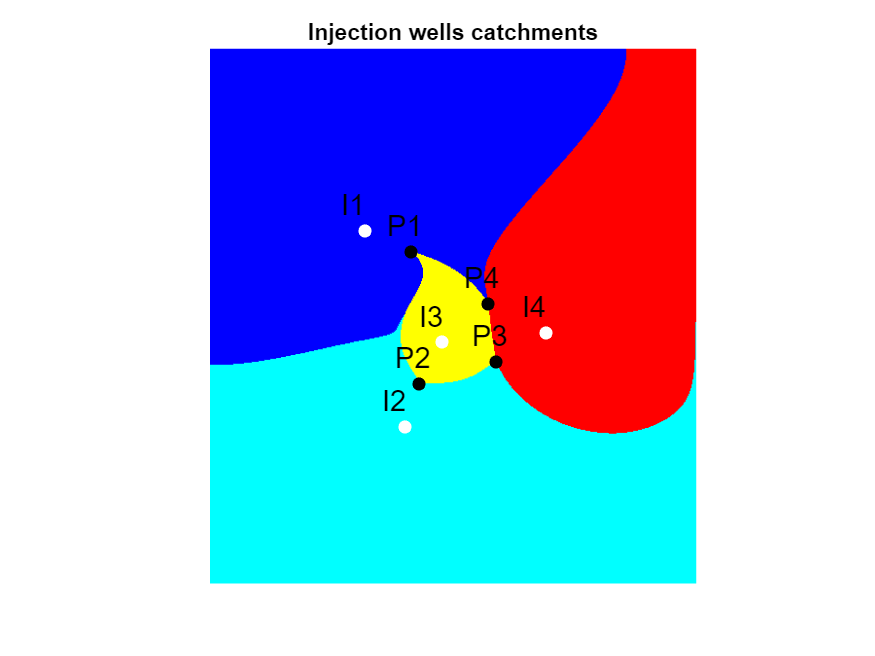

figure;
colormap(jet(4));
plotCellData(G2D,inj_well_index,'EdgeColor','none');
axis tight equal off; colorbar off; 
title('Injection wells catchments'); 
xlabel('X(m)'); ylabel('Y(m)');
hold on; 
scatter(xinj,yinj,40,'w','filled');
scatter(xpmp,ypmp,40,'k','filled');
text([xinj,xpmp]-500, [yinj,ypmp]+500, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
hold off;

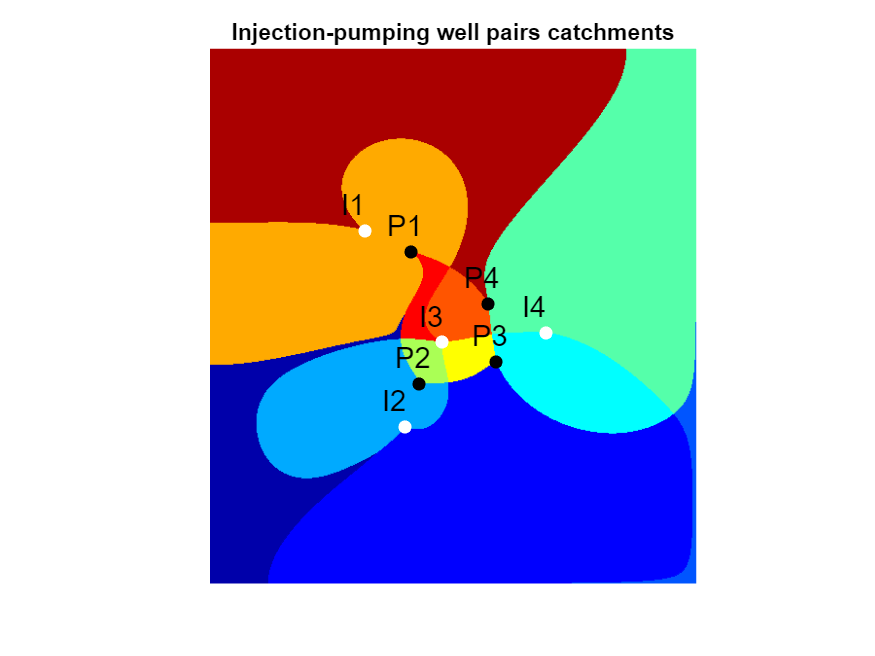

[well_pair,~,partition_pair] = unique([inj_well_index,pump_well_index],'rows','stable'); 
figure;
colormap(jet(size(well_pair,1)));
plotCellData(G2D,partition_pair,'EdgeColor','none');
axis tight equal off; colorbar off; 
title('Injection-pumping well pairs catchments'); 
xlabel('X (m)'); ylabel('Y (m)');
hold on; 
scatter(xinj,yinj,40,'w','filled');
scatter(xpmp,ypmp,40,'k','filled');
text([xinj,xpmp]-500, [yinj,ypmp]+500, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
% Add legend 
% legend(gca,'I1-P4','I1-P2','I1-P3','I1-P1','I3-P2','I3-P3','I2-P1','I2-P2', ...
%    'I4-P4','I2-P3','I2-P4','I4-P3', ...
%    'Location','Best');
hold off;

## Forward travel time simulation 

In forward direction, i.e. times of particles travel from injection wells to actual position in the aquifer 

tic;
at_forward = travelTime(Grid, V, W, true);
toc;

Elapsed time is 0.143607 seconds.


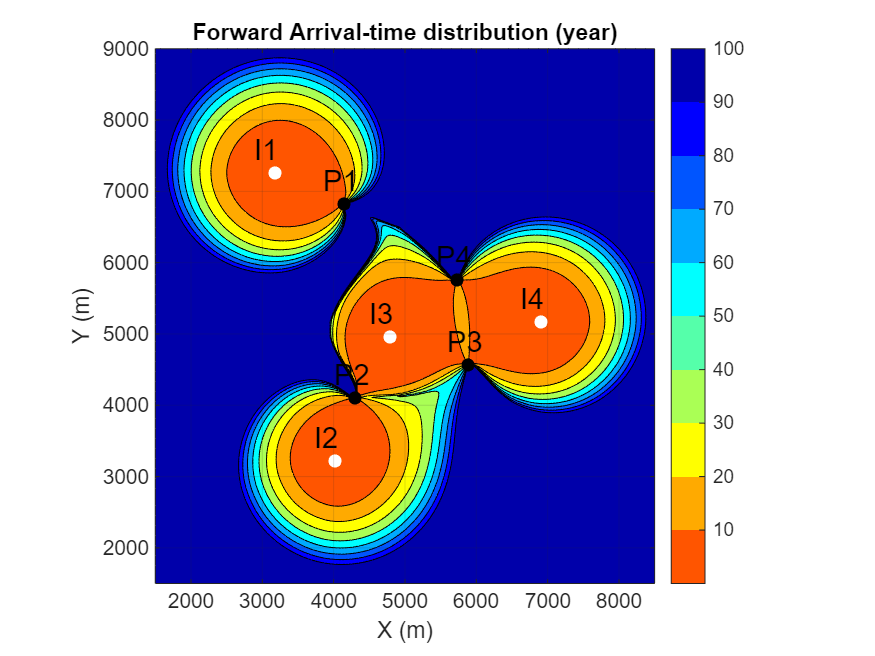

figure; 
colormap(flipud(jet(10)));
opt.fill = 'on';
plotContourData(G2D,at_forward/year,opt,'LevelList',0:12.5:100);
axis tight equal; axis(1e3*[1.5,8.5,1.5,9]); grid on; colorbar;
title('Forward Arrival-time distribution (year)'); 
xlabel('X (m)'); ylabel('Y (m)');
hold on; 
scatter(xinj,yinj,40,'w','filled');
scatter(xpmp,ypmp,40,'k','filled');
text([xinj,xpmp]-300, [yinj,ypmp]+300, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
hold off;

Forward arrival times at wells: 

for w = 1 : length(W)
   disp (['Travel time at well ', num2str(w), ' ', num2str(at_forward(W(w).cells(1))/year)]);
end

Travel time at well 1 0.0021429
Travel time at well 2 0.0026021
Travel time at well 3 0.0021429
Travel time at well 4 0.0021429
Travel time at well 5 118.535
Travel time at well 6 61.1641
Travel time at well 7 167.6157
Travel time at well 8 252.7856


tic;
at_backward = travelTime(Grid, V, W, false);
toc;

Elapsed time is 0.142319 seconds.


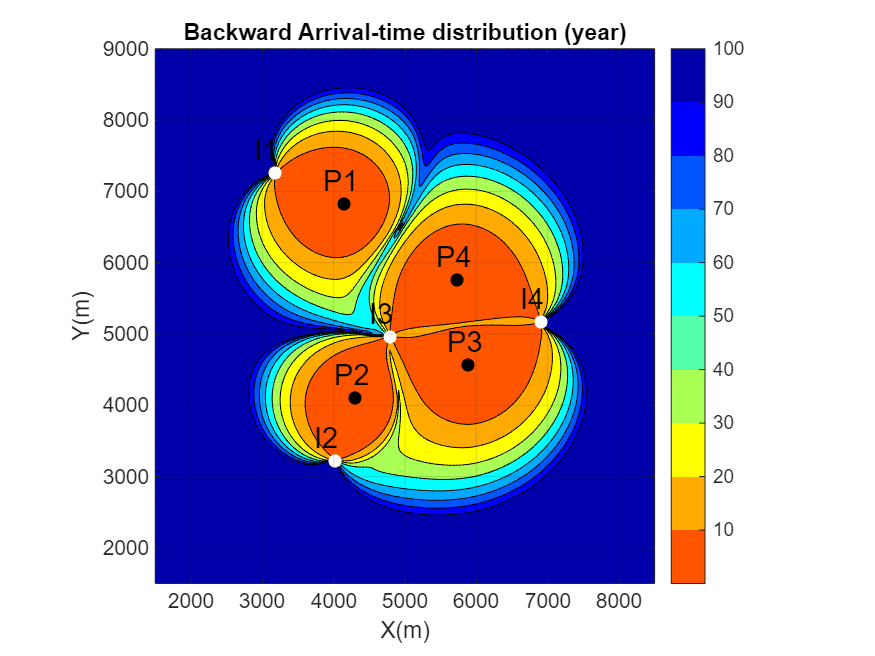

figure; 
colormap(flipud(jet(10)));
opt.fill = 'on';
plotContourData(G2D,at_backward/year,opt,'LevelList',0:12.5:100);
axis tight equal; axis(1e3*[1.5,8.5,1.5,9]); grid on; colorbar;
title('Backward Arrival-time distribution (year)'); 
xlabel('X(m)'); ylabel('Y(m)');
hold on; 
scatter(xinj,yinj,40,'w','filled');
scatter(xpmp,ypmp,40,'k','filled');
text([xinj,xpmp]-300, [yinj,ypmp]+300, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
hold off;

Backward arrival times at injection wells: 

for w = 1 : length(W)
   disp (['Backward travel time at well ', num2str(w), ' ', num2str(at_backward(W(w).cells(1))/year)]);
end

Backward travel time at well 1 212.7523
Backward travel time at well 2 273.5468
Backward travel time at well 3 19.589
Backward travel time at well 4 131.6916
Backward travel time at well 5 0.0021429
Backward travel time at well 6 0.0026021
Backward travel time at well 7 0.0021429
Backward travel time at well 8 0.0021429


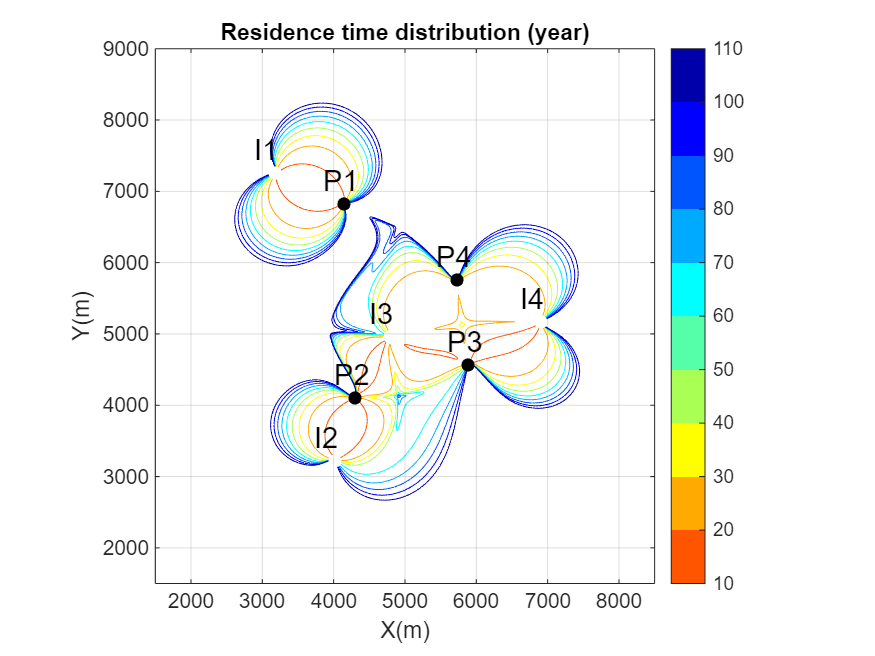

residence_time = at_forward+at_backward;
figure; 
colormap(flipud(jet(10)));
opt.fill = 'off';
plotContourData(G2D,residence_time/year,opt,'LevelList',10:12.5:110);
axis tight equal; axis(1e3*[1.5,8.5,1.5,9]); grid on; colorbar;
title('Residence time distribution (year)'); 
xlabel('X(m)'); ylabel('Y(m)');
hold on; 
scatter(xinj,yinj,40,'w','filled');
scatter(xpmp,ypmp,40,'k','filled');
text([xinj,xpmp]-300, [yinj,ypmp]+300, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
hold off;

for w = 1 : length(W)
   disp (['Residence time at well ', W(w).name, ' ', num2str(residence_time(W(w).cells(1))/year)]);
end

Residence time at well I1 212.7545
Residence time at well I2 273.5494
Residence time at well I3 19.5912
Residence time at well I4 131.6937
Residence time at well P1 118.5371
Residence time at well P2 61.1667
Residence time at well P3 167.6179
Residence time at well P4 252.7877


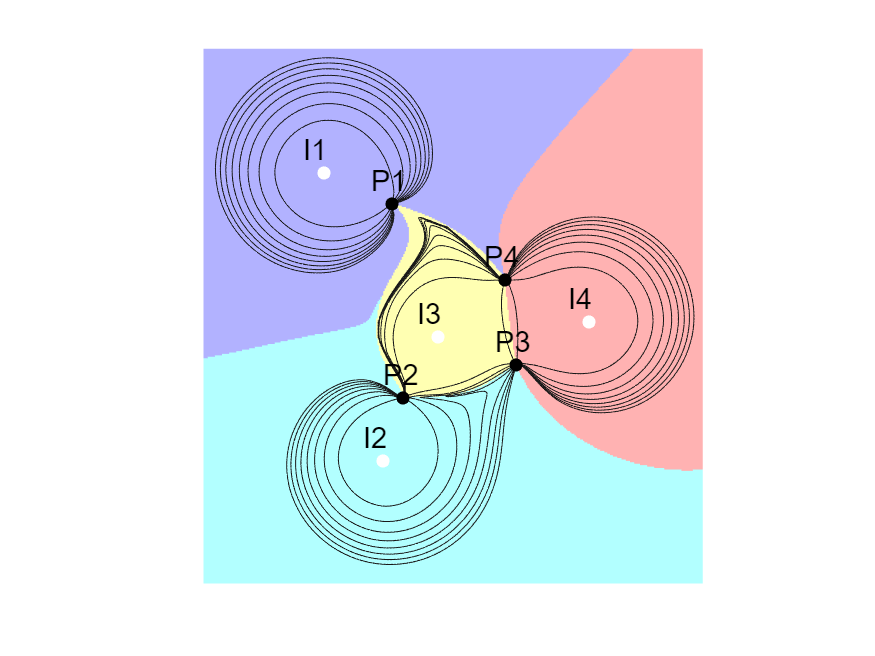

figure;
colormap(jet(4));
plotCellData(G2D,inj_well_index,'EdgeColor','none', 'FaceAlpha', 0.3);
axis tight equal off; colorbar off; axis(1e3*[1.5,8.5,1.5,9]); grid on;
hold on; 
colormap([0.1 0.1 0.1]);
opt.fill = 'off';
plotContourData(G2D,at_forward/year,opt,'LevelList',0:12.5:100);
scatter(xinj,yinj,40,'w','filled');
scatter(xpmp,ypmp,40,'k','filled');
text([xinj,xpmp]-300, [yinj,ypmp]+300, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
hold off;

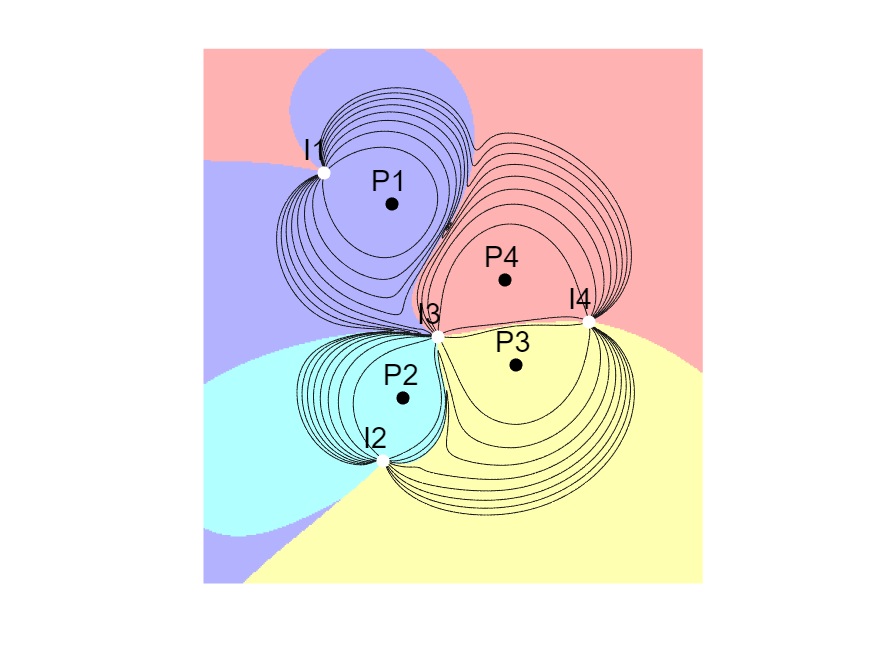

figure;
colormap(jet(4));
plotCellData(G2D,pump_well_index,'EdgeColor','none', 'FaceAlpha', 0.3);
axis tight equal off; colorbar off; axis(1e3*[1.5,8.5,1.5,9]); grid on;
hold on; 
colormap([0.1 0.1 0.1]);
opt.fill = 'off';
plotContourData(G2D,at_backward/year,opt,'LevelList',0:12.5:100);
scatter(xinj,yinj,40,'w','filled');
scatter(xpmp,ypmp,40,'k','filled');
text([xinj,xpmp]-300, [yinj,ypmp]+300, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
hold off;

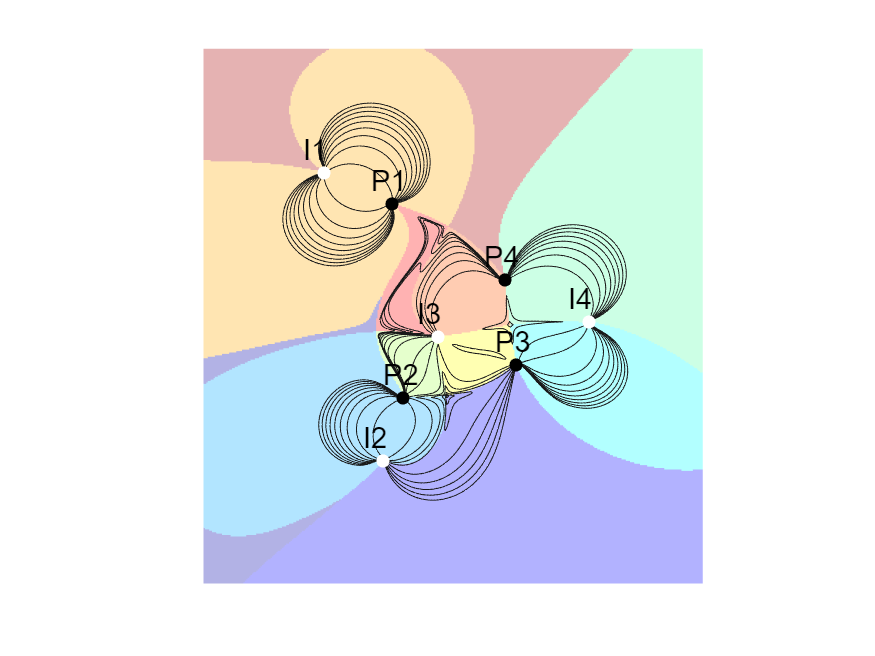

figure;
colormap(jet(size(well_pair,1)));
plotCellData(G2D,partition_pair,'EdgeColor','none', 'FaceAlpha', 0.3);
axis tight equal off; colorbar off; axis(1e3*[1.5,8.5,1.5,9]); grid on;
hold on; 
colormap([0.1 0.1 0.1]);
opt.fill = 'off';
plotContourData(G2D,residence_time/year,opt,'LevelList',10:12.5:110);
scatter(xinj,yinj,40,'w','filled');
scatter(xpmp,ypmp,40,'k','filled');
text([xinj,xpmp]-300, [yinj,ypmp]+300, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);

% Author: M.A. Sbai, Ph.D.
%
% Copyright (C) 2024 Mohammed Adil Sbai
%
% This program is free software: you can redistribute it and/or modify it
% under the terms of the GNU General Public License as published by the
% Free Software Foundation, either version 3 of the License, or (at your
% option) any later version.
%
% This program is distributed in the hope that it will be useful, but 
% WITHOUT ANY WARRANTY; without even the implied warranty of
% MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the GNU General
% Public License for more details.
%
% You should have received a copy of the GNU General Public License along
% with this program. If not, see <http://www.gnu.org/licenses/>.